Creating the Learning Factory Environment

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment4();

matrix_map = 30×30 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0

obstacles

obstacles =      5    27
     5    26
     5    25
     5    24
     5    23
     5    22
     5    18
     5    17
     5    16
     5    15


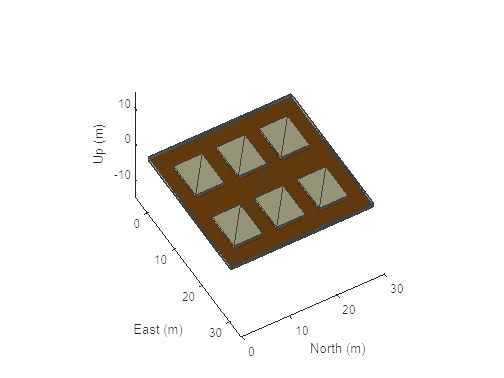

show3D(scenario);
lightangle(-45,30);
view(60,50);

Reinforcement Learning stuff

points = [];
counter = 0

counter = 0

rng(69)
while counter < 50
    counter = counter + 1;

    isvalid = false;
    while ~isvalid        
        rows = randperm(gridSize(1),1);
        cols = randperm(gridSize(2),1);
        position = [rows' cols'];
        if ~isempty(points)
            if ~any(ismember(position, obstacles, 'rows')) && ~any(ismember(position, points, 'rows')) 
                isvalid = true;
                points = [points; position];
            end
        elseif ~any(ismember(position, obstacles, 'rows')) 
            isvalid = true;
            points = position;
        end
    end
end
points

points =     17     8
     4     2
    21    21
     3    10
    23    10
    15     6
    16     9
     9    21
     8    21
    13    12


fname = sprintf('experiment_points/experiment_4_points', 'points');
save(fname)
 